Citation: The code is adapted from UMich's Control Tutorials with needed changes. The tutorial page is [https://ctms.engin.umich.edu/CTMS/index.php?example=InvertedPendulum&section=SystemModeling](https://ctms.engin.umich.edu/CTMS/index.php?example=InvertedPendulum&section=SystemModeling)

## **Transfer Function**

Based on linearized system equations with small angle approximation.

(M)     |  mass of the cart                                             |   0.5 kg

(m)     |  mass of the pendulum                                   |   0.2 kg

(b)      |  coefficient of friction for cart                           |   0.1 N/m/sec

(l)       |  length to pendulum center of mass                |   0.3 m

(I)       |  mass moment of inertia of the pendulum      |   0.006 kg.m^2

(F)      |  force applied to the cart                                 |   input

(x)      |  cart position coordinate                                  |   output 

(theta)|  pendulum angle from vertical (down)             |   output

% Specify physical characteristics
M = 0.5;
m = 0.2;
b = 0.1;
I = 0.006;
g = 9.8;
l = 0.3;
q = (M+m)*(I+m*l^2)-(m*l)^2;
% Creates special variable s to be used in rational expression
s = tf('s');

P_cart = (((I+m*l^2)/q)*s^2 - (m*g*l/q))/(s^4 + (b*(I + m*l^2))*s^3/q - ((M + m)*m*g*l)*s^2/q - b*m*g*l*s/q);
P_pend = (m*l*s/q)/(s^3 + (b*(I + m*l^2))*s^2/q - ((M + m)*m*g*l)*s/q - b*m*g*l/q);

sys_tf = [P_cart ; P_pend];

inputs = {'u'};
outputs = {'x'; 'theta'};

set(sys_tf,'InputName',inputs)
set(sys_tf,'OutputName',outputs)

sys_tf

sys_tf =
 
  From input "u" to output...
                       4.182e-06 s^2 - 0.0001025
   x:  ---------------------------------------------------------
       2.3e-06 s^4 + 4.182e-07 s^3 - 7.172e-05 s^2 - 1.025e-05 s
 
                                1.045e-05 s
   theta:  -----------------------------------------------------
           2.3e-06 s^3 + 4.182e-07 s^2 - 7.172e-05 s - 1.025e-05
 
Continuous-time transfer function.



## Analysis

### Open Loop Impulse Response

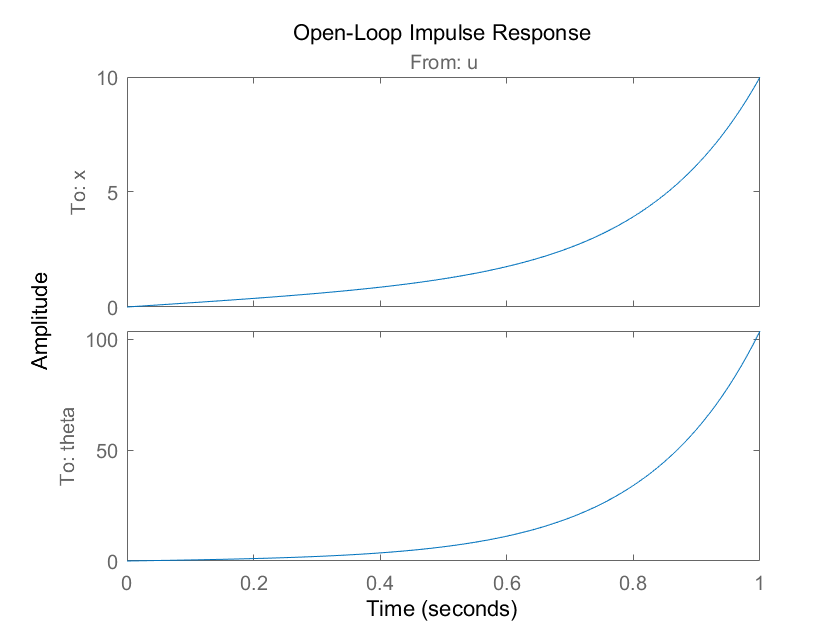

t=0:0.01:1;
% Apply an impulsive force on the cart
impulse(sys_tf,t);
title('Open-Loop Impulse Response')

### Open Loop Step Response

Apply a 1N step.

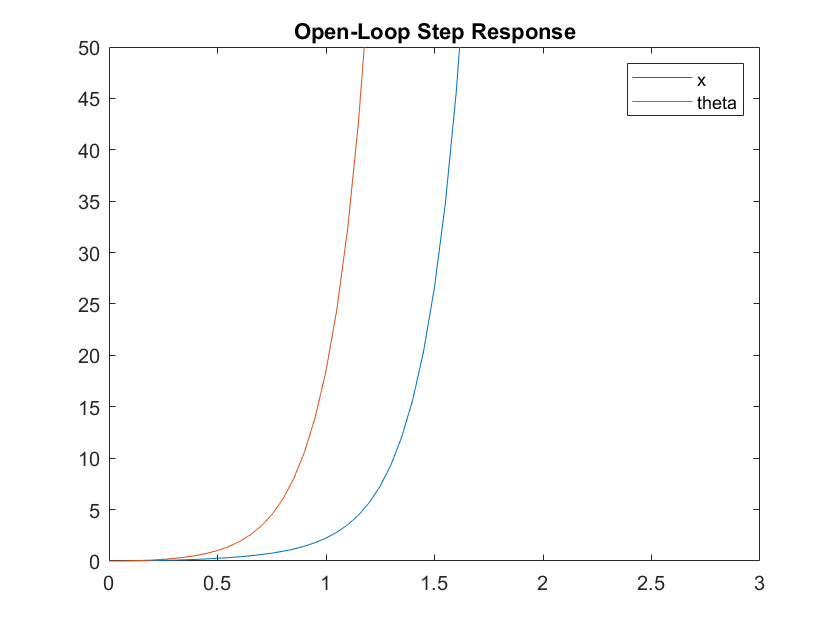

t = 0:0.05:10;
u = ones(size(t));
[y,t] = lsim(sys_tf,u,t);
plot(t,y)
title('Open-Loop Step Response')
axis([0 3 0 50])
legend('x','theta')

## PID Control

Assume SISO, ignore cart position x

Kp = 1;
Ki = 1;
Kd = 1;
C = pid(Kp,Ki,Kd);
T = feedback(P_pend,C);
% Closed Loop Transfer Function
T

T =
 
                        1.045e-05 s^2
  ---------------------------------------------------------
  2.3e-06 s^4 + 1.087e-05 s^3 - 6.126e-05 s^2 + 2.091e-07 s
 
Continuous-time transfer function.



Closed-loop impulse response with kp, ki, kd = 1

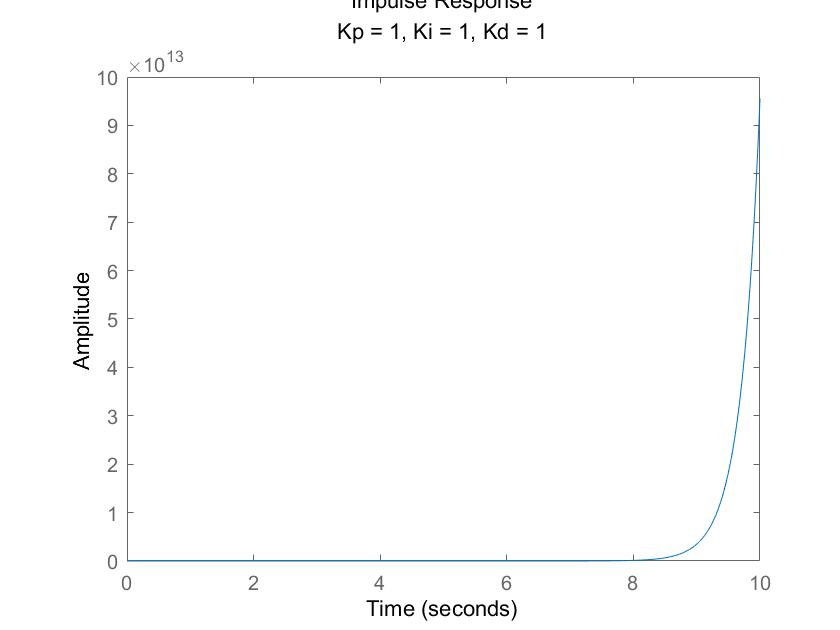

t=0:0.01:10;
impulse(T,t)
title({'Impulse Response'; 'Kp = 1, Ki = 1, Kd = 1'});

Tune

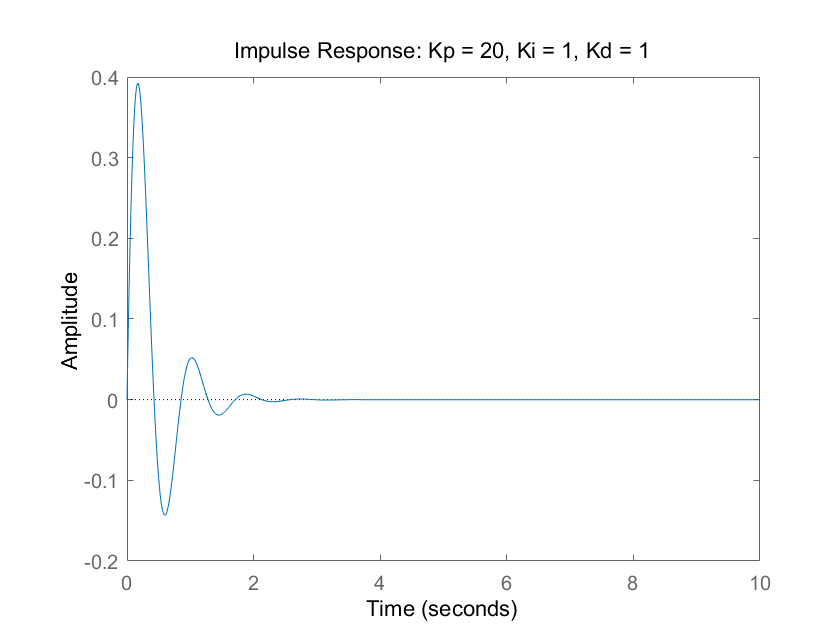

Kp = 20;
Ki = 1;
Kd = 1;
C = pid(Kp,Ki,Kd);
T = feedback(P_pend,C);
t=0:0.01:10;
impulse(T,t)
title(['Impulse Response: ', 'Kp = ', num2str(Kp), ', Ki = ', num2str(Ki), ', Kd = ', num2str(Kd)]);

## Cart's Position Goes Unbounded

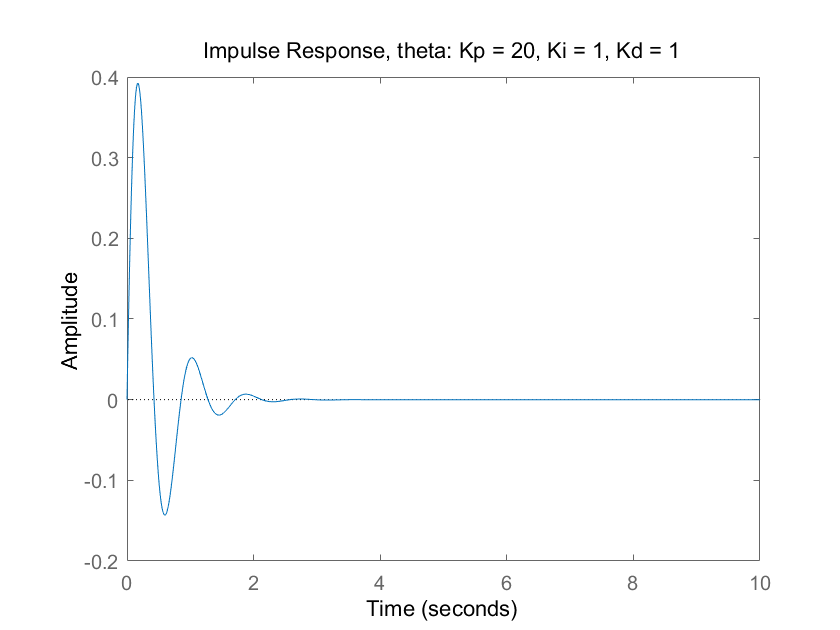

Kp = 20;
Ki = 1;
Kd = 1;
C = pid(Kp,Ki,Kd);
T = feedback(P_pend,C);
t=0:0.01:10;
impulse(T,t)
title(['Impulse Response, theta: ', 'Kp = ', num2str(Kp), ', Ki = ', num2str(Ki), ', Kd = ', num2str(Kd)]);

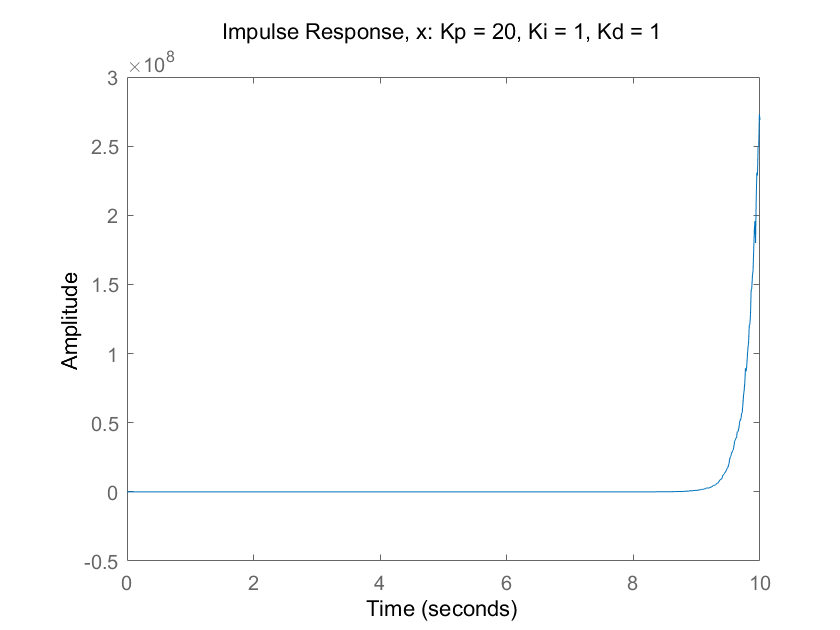

T2 = feedback(1,P_pend*C)*P_cart;
t = 0:0.01:10;
impulse(T2, t);
title(['Impulse Response, x: ', 'Kp = ', num2str(Kp), ', Ki = ', num2str(Ki), ', Kd = ', num2str(Kd)]);

## Root Locus Diagram

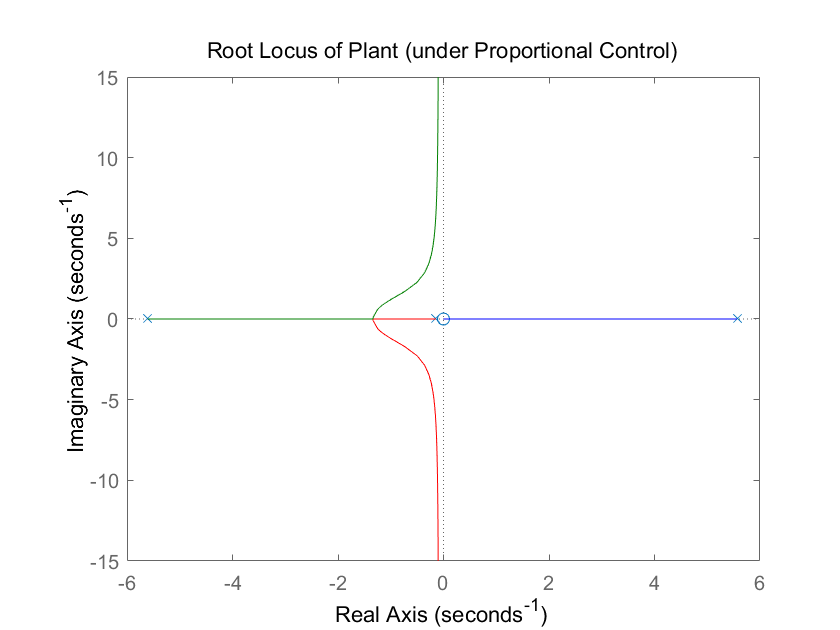

rlocus(P_pend)
title('Root Locus of Plant (under Proportional Control)')

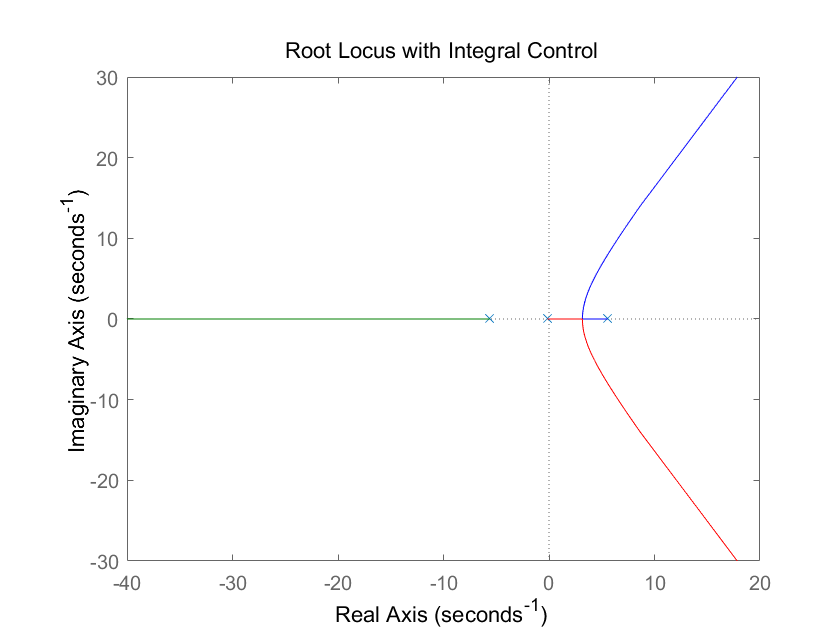


C = 1/s;
rlocus(C*P_pend)
title('Root Locus with Integral Control')

### Root Locus With PID

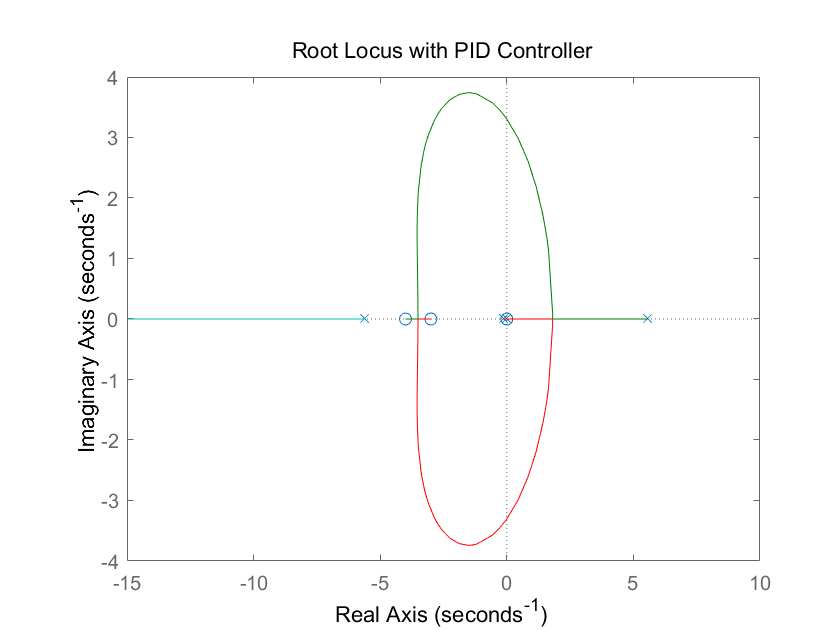

z = [-3 -4];
p = 0;
k = 1;
C = zpk(z,p,k);
rlocus(C*P_pend)
title('Root Locus with PID Controller')